# **Project 1 Draft - Mask Effectivness**

**By Michaela Fox and Ashley Yang**

## **Question**

Our motivating question is how effective do masks need to be to cut the peak number of infected persons by 50%? This is a predictive type of question, since we are trying to predict the number of future infected persons based on mask effectiveness. We believe this to be an important question as knowing the impact of mask effectiveness gives us more information to work with about how to best protect people in times of illness. For instance, mask companies may use this information to adjust their manufacturing process of masks to better fit the necessary mask effectivity value.

In order to understand this motivating question and our modeling choices, we needed to have more background information on what “mask effectivity” means, as well as the existing kinds of masks with their corresponding effectivity. Our literature search results are as follows:

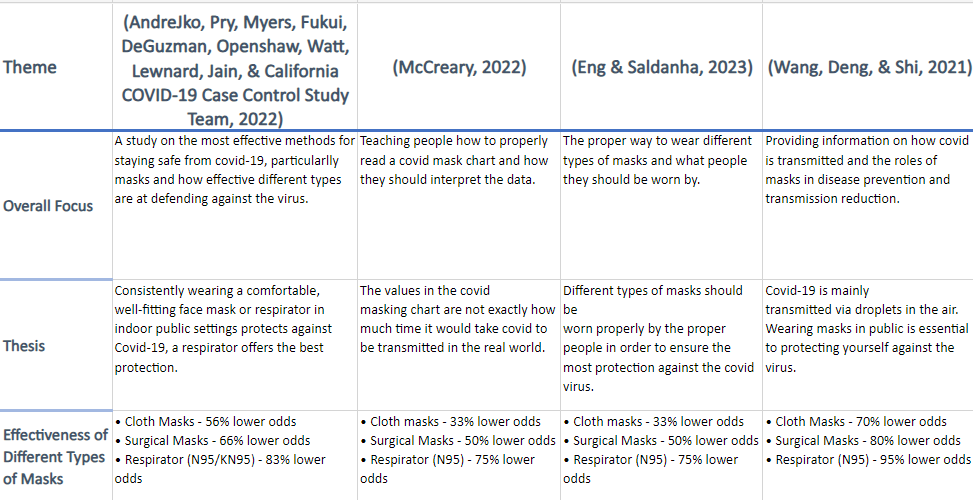

## **Methodology/Model**

	Our model is as follows: 

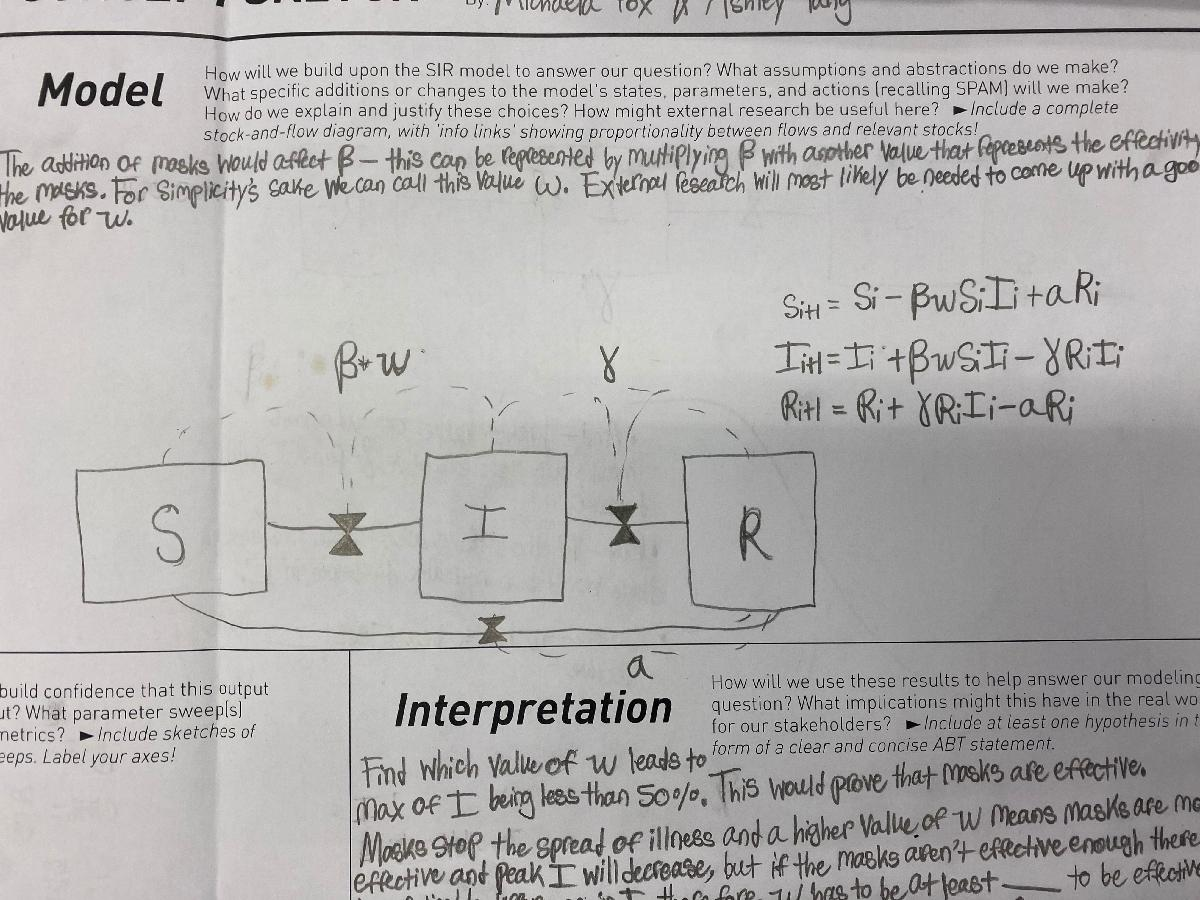

    We made the assumption that everyone in our model is wearing the same type of mask constantly, in order to simplify external factors and just focus on mask effectiveness itself. Each stock represents the following: the “S” stock represents the amount of susceptible people, the “I” stock represents the amount of infected people, the “R” stock represents the amount of recovered people. Each flow represents the following: the “beta omega” flow represents the infection rate (where beta represents the raw infection rate, and omega represents the ineffectivity percentage of masks), the “gamma” flow represents the recovery rate, and the “theta” flow represents the reinfectivity rate. 

(still need to do discussion of parameters, verification facts, and assert statements)

## **Result**

Without masks, this is our curve with the original data:

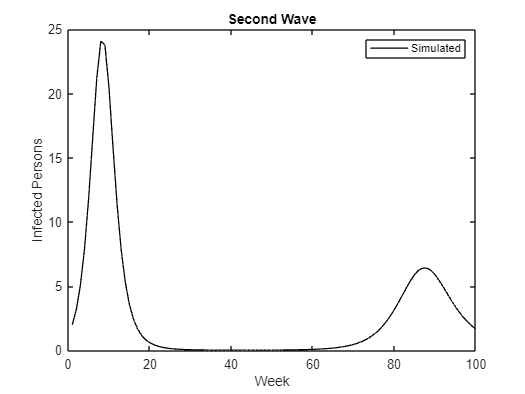

% Original simulation
beta = 1 / 88; % Infection rate (New / Susceptible / Infected / day)
gamma = 1 / 2; % Recovery rate (1 / day)
theta = 1 / 62; % Re-suspectible rate 1 / days
week_end = 100;
i_1 = 2;       % Initial count of infected persons
s_1 = 100 - i_1;
r_1 = 0;

[S_two, I_two, R_two, W_two] = simulate_sir_v3(s_1, i_1, r_1, beta, gamma, theta, week_end);

% Plot the fitted simulation
figure()
plot(W_two, I_two, 'k-', 'LineWidth', 1, 'DisplayName', 'Simulated'); hold on
%plot(W_two, S_two, 'DisplayName', 'S')
%plot(W_two, R_two, 'DisplayName', 'R')
xlabel("Week")
ylabel("Infected Persons")
legend()
title("Second Wave")

I_max = max(I_two);
I_half = I_max / 2; % half of infected peak

The metric we chose was the ineffectivity of masks. This is an appropriate metric because it can be easily implemented in our model and will show how the masks affect the number of infected people. The results we generated using our model, as shown below, were that masks needed to be 26% effective at protecting against the virus to decrease the max number of infected by half.

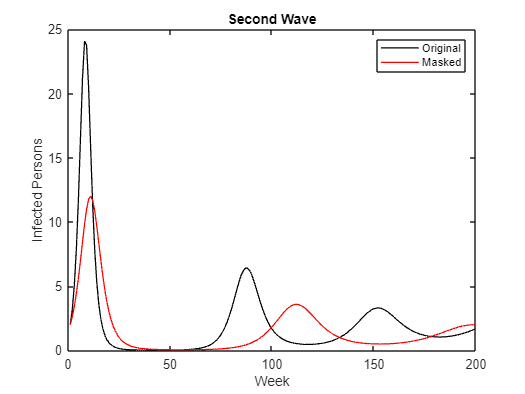

% overall graph again but with masked included
betaM = 1 / 88; % Infection rate (New / Susceptible / Infected / day)
gammaM = 1 / 2; % Recovery rate (1 / day)
thetaM = 1 / 62; % Re-suspectible rate 1 / days
omega = 0.2626; % effectivity
beta1 = betaM * (1 - omega); 
week_end = 200;
i_1 = 2;       % Initial count of infected persons
s_1 = 100 - i_1;
r_1 = 0;
I_max = max(I_two);
I_half = I_max / 2; % half of infected peak

[S, I, R, W] = simulate_sir_v3(s_1, i_1, r_1, beta, gamma, theta, week_end);
[S_mask, I_mask, R_mask, W_mask] = simulate_sir_v3(s_1, i_1, r_1, beta1, gamma, theta, week_end);

% Plot the fitted simulation
figure()
plot(W, I, 'k-', 'LineWidth', 1, 'DisplayName', 'Original'); hold on
plot(W_mask, I_mask, 'r-', 'LineWidth', 1, 'DisplayName', 'Masked');
%plot(W_two, S_two, 'DisplayName', 'S')
%plot(W_two, R_two, 'DisplayName', 'R')
xlabel("Week")
ylabel("Infected Persons")
legend()
title("Second Wave")

This is our parameter sweep using our chosen metric of mask ineffectiivty (represented by omega).

% Parameter sweep
% Sweep above and below the nominal values
Alpha_all = linspace(0, 1, 100); % ineffectivity
Omega_all = 1 - Alpha_all; % effectivity
Beta_all = beta * (1 - Omega_all);

Max_all = zeros(size(Beta_all));
for i = 1:100
    beta_temp = Beta_all(i);
    [S, I, R, W] = simulate_sir(s_1, i_1, r_1, beta_temp, gamma, week_end);
    Max_all(i) = max(I);
end 

index = find(abs(Max_all - I_half) < 0.5, 1); % find which value gets you half the peak
Omega_Desired = Omega_all(index) % least omega point that gets you half infected

Omega_Desired = 0.2626

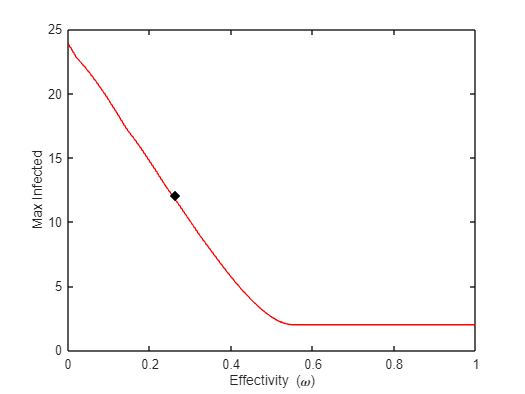


figure
plot(Omega_all, Max_all, 'r'); hold on
plot(Omega_Desired, I_half, 'kx', 'LineWidth', 6); % plotting which effectivity value gets you half
xlabel('Effectivity (\omega)')
ylabel('Max Infected')

The most important trends in our parameter sweep were that there is a linear decrease in the max number of infected people as effectivity of masks increases from 0 to 0.5. If effectivity is greater than about 0.5 then there is no change to the max number of infected people. These results mean that masks need to be 26% effective at protecting against the virus in order to cut the max number of infected in half.

## **Interpretation**

    The results tell us that masks need to be 26% effective to cut the peak number of infected individuals by 50%. The limitations of our model are primarily that it cannot predict how many people are wearing masks or what kind of masks they are wearing. In the future, we might try and implement different types of masks to see which ones are best at protecting against the virus and can further decrease the max number of infected, possibly by 75%. We might also try and see how many people need to be wearing masks to cut the max number of infected by 50%.

## **Model Versions**

### **Improved Version**

% ROUGH companies and the connection between the metric and stakeholders;
%
% Original simulation
beta1 = 1 / 88; % Infection rate (New / Susceptible / Infected / day)
gamma = 1 / 2; % Recovery rate (1 / day)
theta = 1 / 62; % Re-suspectible rate 1 / days
week_end = 100;
i_1 = 2;       % Initial count of infected persons
s_1 = 100 - i_1;
r_1 = 0;

[S_two, I_two, R_two, W_two] = simulate_sir_v3(s_1, i_1, r_1, beta1, gamma, theta, week_end);

% Plot the fitted simulation
figure()
plot(W_two, I_two, 'k-', 'LineWidth', 1, 'DisplayName', 'Simulated'); hold on
%plot(W_two, S_two, 'DisplayName', 'S')
%plot(W_two, R_two, 'DisplayName', 'R')
xlabel("Week")
ylabel("Infected Persons")
legend()
title("Second Wave")

I_max = max(I_two);
I_half = I_max / 2; % half of infected peak


% Parameter sweep
% Sweep above and below the nominal values
Omega_all = linspace(0, 1, 100); % ineffectivity
Beta_all = beta1 * Omega_all;

Max_all = zeros(size(Beta_all));
for i = 1:100
    beta_temp = Beta_all(i);
    [S, I, R, W] = simulate_sir(s_1, i_1, r_1, beta_temp, gamma, week_end);
    Max_all(i) = max(I);
end 

index = find(abs(Max_all - I_half) < 0.5, 1); % find which value gets you half the peak
Omega_Desired = Omega_all(index) % least omega point that gets you half infected

figure
plot(Omega_all, Max_all, 'r'); hold on
plot(Omega_Desired, I_half, 'x'); % plotting which ineffectivity 
xlabel('Ineffectivity (\omega)')
ylabel('Max Infected')

% overall graph again but with masked included
beta = 1 / 88; % Infection rate (New / Susceptible / Infected / day)
gamma = 1 / 2; % Recovery rate (1 / day)
theta = 1 / 62; % Re-suspectible rate 1 / days
omega = 0.7374;
beta1 = beta * omega;
week_end = 200;
i_1 = 2;       % Initial count of infected persons
s_1 = 100 - i_1;
r_1 = 0;

[S, I, R, W] = simulate_sir_v3(s_1, i_1, r_1, beta, gamma, theta, week_end);
[S_mask, I_mask, R_mask, W_mask] = simulate_sir_v3(s_1, i_1, r_1, beta1, gamma, theta, week_end);

% Plot the fitted simulation
figure()
plot(W, I, 'k-', 'LineWidth', 1, 'DisplayName', 'Original'); hold on
plot(W_mask, I_mask, 'r-', 'LineWidth', 1, 'DisplayName', 'Masked');
%plot(W_two, S_two, 'DisplayName', 'S')
%plot(W_two, R_two, 'DisplayName', 'R')
xlabel("Week")
ylabel("Infected Persons")
legend()
title("Second Wave")


### **First Iteration**

% companies and the connection between the metric and stakeholders; 

% Configure the simulation
beta1 = 1 / 88; % Infection rate (New / Susceptible / Infected / day)
%omega_middle = 0.5; % mask ineffectivity rate
gamma = 1 / 2; % Recovery rate (1 / day)
theta = 1 / 62; % Re-suspectible rate 1 / days
week_end = 100;
i_1 = 2;       % Initial count of infected persons
s_1 = 100 - i_1;
r_1 = 0;


% Sweep above and below the nominal values
Omega_all = linspace(0, 1, 100); % ineffectivity

Beta_all = beta1 * Omega_all;



% TODO: Do a parameter sweep over Beta_all, use gamma_middle for all cases
Max_all = zeros(size(Beta_all));
for i = 1:100
    beta_temp = Beta_all(i);
    [S, I, R, W] = simulate_sir(s_1, i_1, r_1, beta_temp, gamma, week_end);
    Max_all(i) = max(I);
end 

figure
plot(Omega_all, Max_all, 'r');
xlabel('Ineffectivity (\omega)')
ylabel('Max Infected')

Getting the second wave plotted 

% Run simulation
[S_two, I_two, R_two, W_two] = simulate_sir_v3(s_1, i_1, r_1, beta1, gamma, theta, week_end);

% Plot the fitted simulation
figure()
plot(W_two, I_two, 'k-', 'LineWidth', 1, 'DisplayName', 'Simulated'); hold on
%plot(W_two, S_two, 'DisplayName', 'S')
%plot(W_two, R_two, 'DisplayName', 'R')
xlabel("Week")
ylabel("Infected Persons")
legend()
title("Second Wave")